# CLS Example

Copyright 2022-2023 Battelle Memorial Institute

This example shows how to compute Classical Least Squares (CLS) predictions. 

## CLS Algorithm

The CLS Algorithm is encapsulated in the following MATLAB function. 

## Concentration Data

The concentrations of the training data are in matrix `C_train` and the concentrations of the validation data are in matrix `C_validation`.  Column 1 corresponds to the concentrations in constituent 1 (benzene). Column 2 corresponds to the concentrations in constituent 2 (polystyrene).  Column 3 corresponds to the concentrations in constituent 3 (gasoline).


$$$$ %
\begin{array}{ccc}%
\begin{array}{rcl}%
C_\textrm{train} & = & %
\begin{array}{rl}%
\begin{array}{c}%
\begin{array}{rrr}%
\textit{benzene} & \textit{polystyrene} & \textit{gasoline} \\%
\end{array}\\%
\left[%
\begin{array}{rrr}%
0  &       0 & 100.0000\\%
5.1309  &       0 &  94.8691\\%
10.0660  &       0 &  89.9300\\%
20.1799  &       0 &  79.8201\\%
40.0120  &       0 &  59.9878\\%
59.9972  &       0 &  40.0028\\%
79.8412  &       0 &  20.1588\\%
89.8273  &       0 &  10.1727\\%
100.0000  &       0 &        0\\%
90.0264  &  9.9736 &        0\\%
80.1375  & 19.8625 &        0\\%
64.9950  & 35.0005 &        0\\%
21.0228  & 45.9197 &  33.0575\\%
49.9507  &  5.0599 &  44.9895\\%
40.0182  & 20.0385 &  39.9433\\%
40.0154  & 10.0036 &  49.9810\\%
30.0059  & 10.0282 &  59.9659\\%
40.0340  & 39.9670 &  19.9990\\%
49.9393  &  3.3748 &  46.6859\\%
46.6501  & 13.4658 &  39.8840\\%
\end{array}%
\right]%
\end{array}%
&%
\begin{array}{r}%
  \\%
  1\\%
  2\\%
  3\\%
  4\\%
  5\\%
  6\\%
  7\\%
  8\\%
  9\\%
  10\\%
  11\\%
  12\\%
  13\\%
  14\\%
  15\\%
  16\\%
  17\\%
  18\\%
  19\\%
  20\\%
\end{array}%
\end{array}%
\end{array}%
& &%
\begin{array}{rcl}%
C_\textrm{validation} & = &%
\begin{array}{rl}%
\begin{array}{c}%
  \begin{array}{rrr}%
    \textit{benzene} & \textit{polystyrene} & \textit{gasoline} \\%
  \end{array}\\%
  \left[%
  \begin{array}{rrr}%
    22.1665 &  39.0384 &  38.7951\\%
    21.6874 &  37.0596 &  41.2530\\%
    22.1665 &  39.6980 &  38.1355\\%
    26.9575 &  40.3576 &  32.6849\\%
    25.9993 &  33.7616 &  40.2391\\%
    23.1247 &  37.0596 &  39.8157\\%
    22.6456 &  39.0384 &  38.3160\\%
    22.6456 &  39.0384 &  38.3160\\%
    27.4366 &  42.3364 &  30.2270\\%
    27.4366 &  37.7192 &  34.8442\\%
    26.4784 &  40.3576 &  33.1640\\%
    26.9575 &  37.7192 &  35.3233\\%
  \end{array}%
  \right]%
\end{array}%
&%
\begin{array}{r}%
  \\%
  1\\%
  2\\%
  3\\%
  4\\%
  5\\%
  6\\%
  7\\%
  8\\%
  9\\%
  10\\%
  11\\%
  12\\%
\end{array}%
\end{array}%
\\%
\\%
\\%
\\%
\\%
\\%
\\%
\\%
\\%
\end{array}%
\end{array}%
$$
$$


Clear variables and load the PNNL napalm data.

clearvars
load pnnl_napalm_data

## Compute CLS

Set up the plot title and color.

title_string = sprintf('CLS');
nConstituents = size(C_validation,2);
colorOrder = pnnl_colorOrder(nConstituents);

Use all the columns of `C_train` to compute CLS.  Use all the columns of `C_validation` to compute RMSEP (root mean square error predicted).  Use the columns of `C_train` to compute RMSEC (root mean square error calibration) and RMSECV (root mean square error cross validation).

Compute CLS

C_predicted = pnnl_cls(A_train,C_train,A_unknown);
C_calibration = pnnl_cls(A_train,C_train,A_train);
C_cross_validation = pnnl_cross_validation(@pnnl_cls,A_train,C_train);


Compute RMSE

RMSEP = pnnl_rmse(C_validation,C_predicted);
RMSEC = pnnl_rmse(C_train,C_calibration);
RMSECV = pnnl_rmse(C_train,C_cross_validation);

Display RMSE

pnnl_display_rmse(title_string,ConstituentNames,...
    RMSEC,RMSECV,RMSEP);

--------------------------------------------------
     CLS       Benzene   Polystyrene      Gasoline
   RMSEC        4.2721        2.3784        5.6857
  RMSECV        5.1043        3.0807        6.7847
   RMSEP         7.895        2.6988        9.1105
--------------------------------------------------


## Plot the results

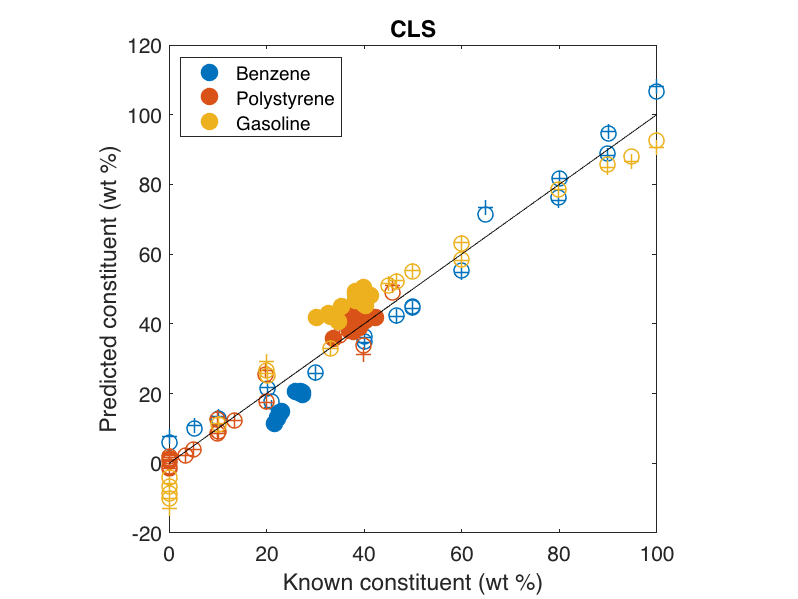

figure
h = gobjects(nConstituents,1);
for k = 1:nConstituents
    % Plot Concentrations
    hold on
    % Validation vs. Predicted
    h(k) = plot(C_validation(:,k),C_predicted(:,k),'.','MarkerSize',35,'Color',colorOrder(k,:),'DisplayName',ConstituentNames{k});
    % Train vs. Calibration
    plot(C_train(:,k),C_calibration(:,k),'o','MarkerSize',10,'LineWidth',1,'Color',colorOrder(k,:))
    % Train vs. Crosss Validation
    plot(C_train(:,k),C_cross_validation(:,k),'+','MarkerSize',10,'LineWidth',1,'Color',colorOrder(k,:))
    % 1-1 line
    line(C_train(:,k),C_train(:,k),'Color','k')
    title(title_string)
    xlabel(['Known constituent (',ConcentrationUnits,')'])
    ylabel(['Predicted constituent (',ConcentrationUnits,')'])
    set(gca,'FontSize',14)
    box on
    axis square
    hold off
end
legend(h,'Location','northwest')

Legend: Dot is predicted. Circle is calibration. Cross is cross-validation.')

# Disclaimer

This material was prepared as an account of work sponsored by an agency of the United States Government. Neither the United States Government nor the United States Department of Energy, nor Battelle, nor any of their employees, nor any jurisdiction or organization that has cooperated in the development of these materials, makes any warranty, express or implied, or assumes any legal liability or responsibility for the accuracy, completeness, or usefulness or any information, apparatus, product, software, or process disclosed, or represents that its use would not infringe privately owned rights.

Reference herein to any specific commercial product, process, or service by trade name, trademark, manufacturer, or otherwise does not necessarily constitute or imply its endorsement, recommendation, or favoring by the United States Government or any agency thereof, or Battelle Memorial Institute. The views and opinions of authors expressed herein do not necessarily state or reflect those of the United States Government or any agency thereof.

PACIFIC NORTHWEST NATIONAL LABORATORY

operated by

BATTELLE

for the

UNITED STATES DEPARTMENT OF ENERGY

under Contract DE-AC05-76RL01830